## Authors and Information

### TNK093  - Project relay

Ebba Österman (ebbos603)

Ola Andersson (olaan012)

Vilma Björk (viloh654)

Tobias Aspegårdh (tobas704)

clear
clc
format compact

## Variables

% Declare variables
global Q0 Psd Psr Prd TP_D lamR %dynamic variables
global joint_prob1 joint_prob2 %result-var joint prob. queue case 1, case 2
global PrQ1 PrQ2 PrQ0 %result-var product prob. queue case 3
global PrQ0_M1 PrQ0_M2 PrQ0_M8 %result-var prob. queue case 4
global lamS1 lamS2

## Result Variables

global result_TP_D result_lam_R
global result_JointQueueCase1_1 result_JointQueueCase1_2
global result_JointQueueCase2_1 result_JointQueueCase2_2
global result_PrQ1 result_PrQ2 result_PrQ0
global result_PrQ0_M1 result_PrQ0_M2 result_PrQ0_M8
global result_Q0_lam01 result_Q0_lam09

## Run main code

T = 10000; %nr of time slots
%Run two erasure probability scenarios
for i=1:2

    if i==1
        Psd = 0.15; Psr = 0.75; Prd = 0.9;
    else
        Psd = 0.4; Psr = 0.9; Prd = 0.95;
    end

    % Run for 10 values of lambda: 0:0.1:1
    for j=1:11

        % Arrival probabilities for node 1 and 2
        lamS1 = (j/10)-0.1;
        lamS2 = (j/10)-0.1;

        % Initialize global variables
        init_var();

        % Run for 10 000 time slots
        for t=1:T

            % Run simulation of transmission
            simulation(t);

            % Check for case 4
            if numel(Q0) > 1
                PrQ0_M1=PrQ0_M1+1;
            end
            if numel(Q0) > 2
                PrQ0_M2=PrQ0_M2+1;
            end
            if numel(Q0) > 8
                PrQ0_M8=PrQ0_M8+1;
            end

            % Check for two values of lambda, queue-sizes of R
            if j == 2 %lambda = 0.1
                result_Q0_lam01(i,t)= numel(Q0);
            elseif j == 10 %lambda = 0.9
                result_Q0_lam09(i,t)=numel(Q0);
            end
        end

        % Add values for results arrays
        result_TP_D(i,j)=TP_D/T; %throughput network
        result_lam_R(i,j)=lamR/T; %arrival rate relay node

        % Joint Prob queue case 1
        if i==1
            result_JointQueueCase1_1(1:4,j) = joint_prob1./T;
            result_JointQueueCase2_1(1:4,j) = joint_prob2./T;
        else
            result_JointQueueCase1_2(1:4,j) = joint_prob1./T;
            result_JointQueueCase2_2(1:4,j) = joint_prob2./T;
        end

        % Prob queue case 3
        result_PrQ1(i,j)=PrQ1/T;
        result_PrQ2(i,j)=PrQ2/T;
        result_PrQ0(i,j)=PrQ0/T;

        % Prob queue case 4
        result_PrQ0_M1(i,j)=PrQ0_M1/T;
        result_PrQ0_M2(i,j)=PrQ0_M2/T;
        result_PrQ0_M8(i,j)=PrQ0_M8/T;

    end
end


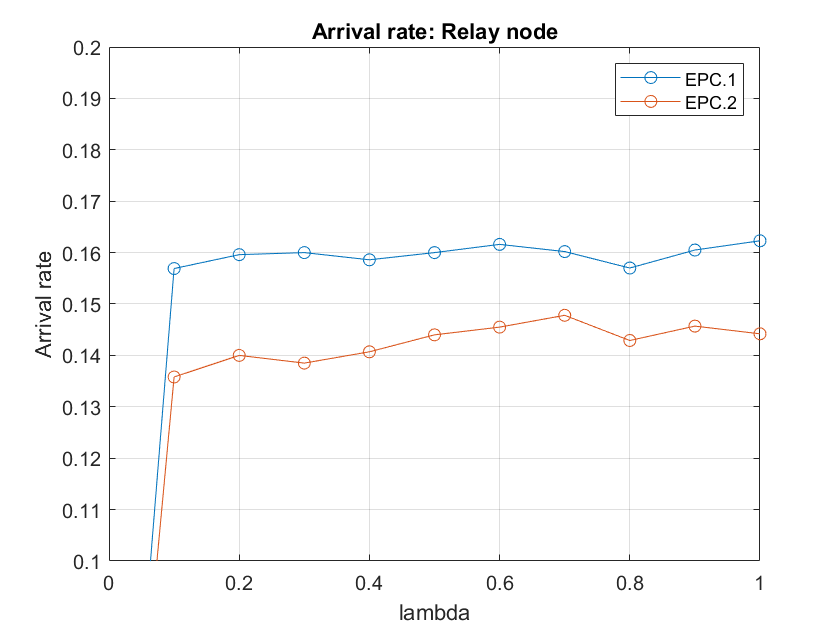

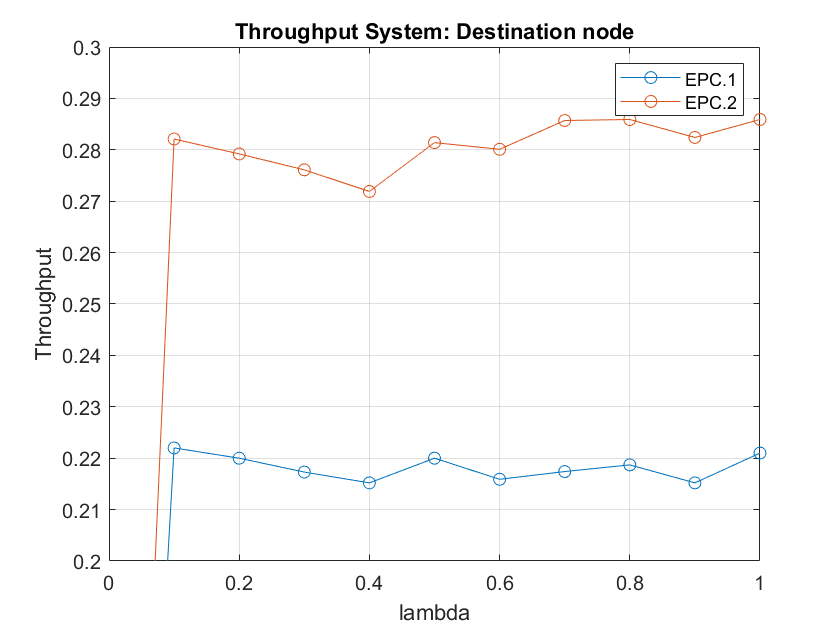

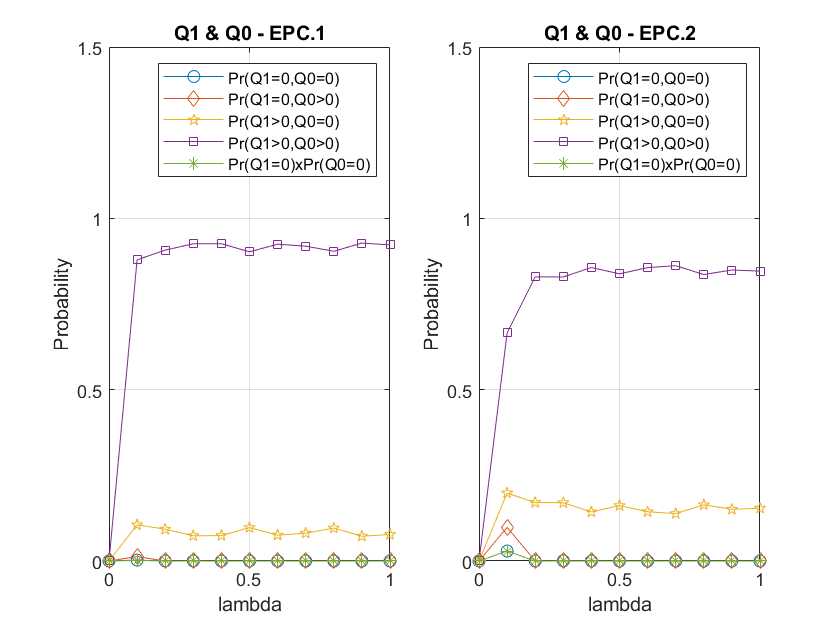

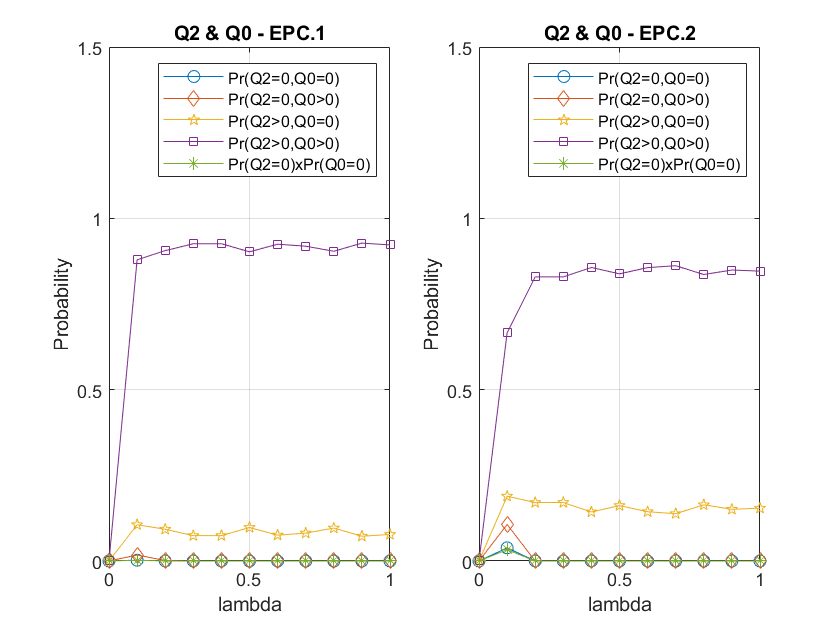

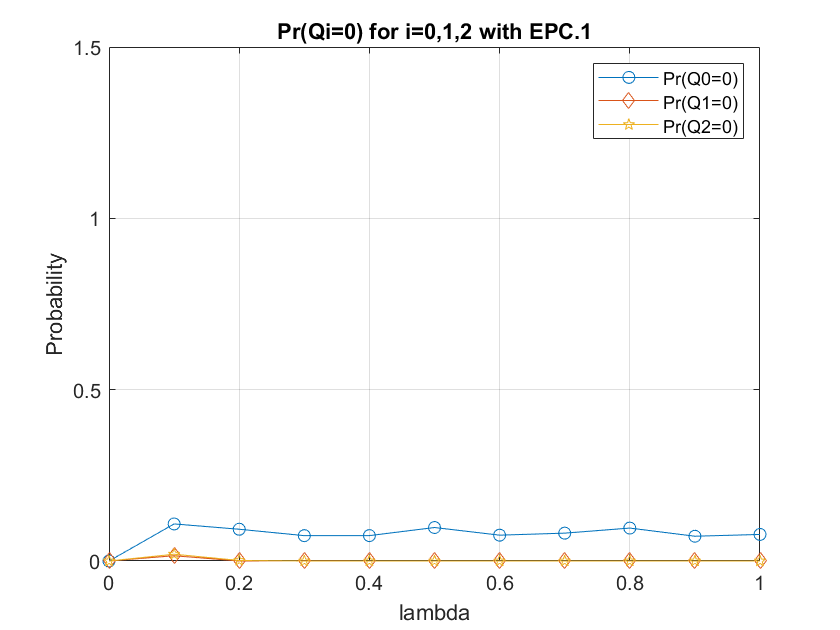

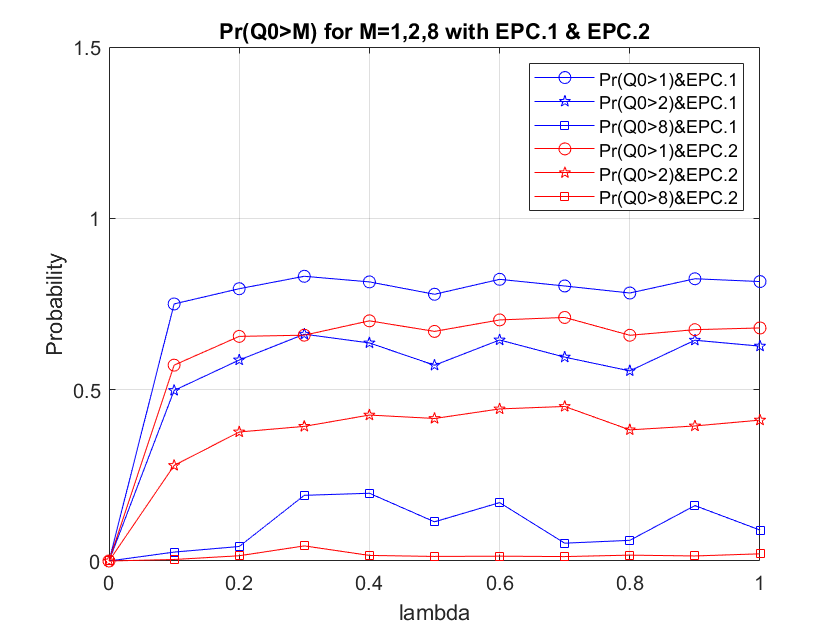

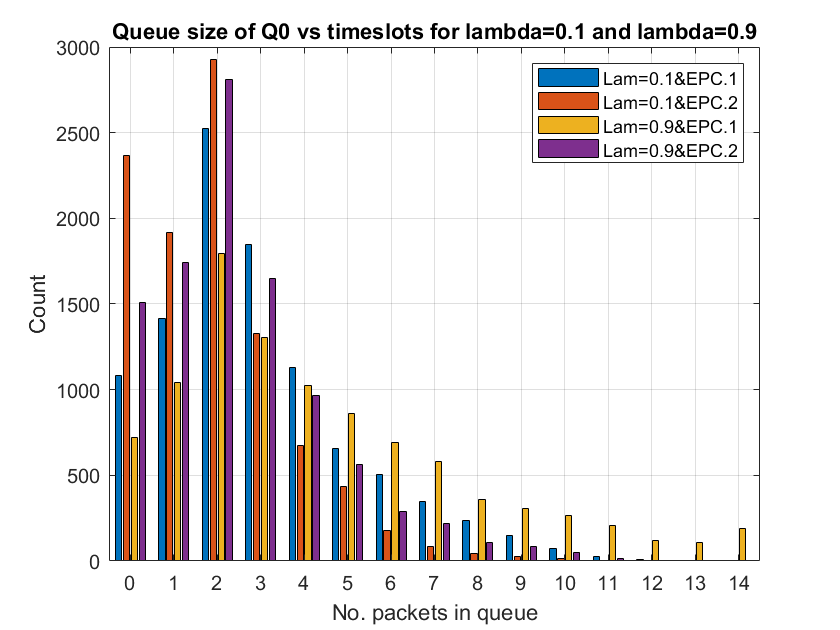

plots();

## Function: Simulation

function simulation(t)

%Declare variables
global Q1 Q2 Q0 %queues for S1,S2 and R
global joint_prob1 joint_prob2 PrQ1 PrQ2 PrQ0
global lamS1 lamS2

%Arrival process for S1 and S2
prob = rand(1);
if prob <= lamS1
    Q1(end+1,1)=t; %add timeslot as packet to S1 queue
end
prob = rand(1);
if prob <= lamS2
    Q2(end+1,1)=t; %add timeslot as packet to S2 queue
end

scenario = 0;
%Start transmission based on scenario
if ~isempty(Q1) && ~isempty(Q2) && ~isempty(Q0)
    scenario = 1; %S1,S2,R has packets in queue
    joint_prob1(4)=joint_prob1(4)+1; %Pr(Q1 > 0, Q0 > 0)
    joint_prob2(4)=joint_prob2(4)+1; %Pr(Q2 > 0, Q0 > 0)
elseif ~isempty(Q1) && ~isempty(Q2) && isempty(Q0)
    scenario = 2; %S1,S2 has packets in queue
    joint_prob1(3)=joint_prob1(3)+1; %Pr(Q1 > 0, Q0 = 0)
    joint_prob2(3)=joint_prob2(3)+1; %Pr(Q2 > 0, Q0 = 0)
    PrQ0 = PrQ0+1; %Pr(Q0=0)
elseif ~isempty(Q1) && isempty(Q2) && ~isempty(Q0) %S1,R has packets in queue
    scenario = 3;
    joint_prob1(4)=joint_prob1(4)+1; %Pr(Q1 > 0, Q0 > 0)
    joint_prob2(2)=joint_prob2(2)+1; %Pr(Q2 = 0, Q0 > 0)
    PrQ2=PrQ2+1; %Pr(Q2=0)
elseif isempty(Q1) && ~isempty(Q2) && ~isempty(Q0) %S2,R has packets in queue
    scenario = 4;
    joint_prob1(2)=joint_prob1(2)+1; %Pr(Q1 = 0, Q0 > 0)
    joint_prob2(4)=joint_prob1(4)+1; %Pr(Q2 > 0, Q0 > 0)
    PrQ1=PrQ1+1; %Pr(Q1=0)
elseif ~isempty(Q1) && isempty(Q2) && isempty(Q0) %S1 has packets in queue
    scenario = 5;
    joint_prob1(3)=joint_prob1(3)+1; %Pr(Q1 > 0, Q0 = 0)
    joint_prob2(1)=joint_prob2(1)+1; %Pr(Q2 = 0, Q0 = 0)
    PrQ2=PrQ2+1; %Pr(Q2=0)
    PrQ0=PrQ0+1; %Pr(Q0=0)
elseif isempty(Q1) && ~isempty(Q2) && isempty(Q0) %S2 has packets in queue
    scenario = 6;
    joint_prob1(1)=joint_prob1(1)+1; %Pr(Q1 = 0, Q0 = 0)
    joint_prob2(3)=joint_prob2(3)+1; %Pr(Q2 > 0, Q0 = 0)
    PrQ1=PrQ1+1; %Pr(Q1=0)
    PrQ0=PrQ0+1; %Pr(Q0=0)
elseif isempty(Q1) && isempty(Q2) && ~isempty(Q0) %R has packets in queue
    scenario = 7;
    joint_prob1(2)=joint_prob1(2)+1; %Pr(Q1 = 0, Q0 > 0)
    joint_prob2(2)=joint_prob2(2)+1; %Pr(Q2 = 0, Q0 > 0)
    PrQ1=PrQ1+1; %Pr(Q1=0)
    PrQ2=PrQ2+1; %Pr(Q2=0)
end
transmission(scenario);
end

## Function: Transmission

function transmission(scenario)

%Declare variables
global collisions

%Probabilites for accessing channel
qs = 0.3; %prob for accessing channel for Si, i=1,2
qr = 0.45; %prob for accessing channel for R

%Simulate transmission scenarios
prob1 = rand(1); prob2 = rand(1); prob0 = rand(1);
switch scenario
    case 1 %S1,S2,R has packets in queue

        if sum(prob1 <= qs && prob2 <= qs && prob0 <= qr) > 1
            collisions=collisions+1;

        elseif prob1 <= qs && prob2 > qs && prob0 > qr %S1 tries to transmit packet
            decode(1); %attempt decoding packet

        elseif prob1 > qs && prob2 <= qs && prob0 > qr %S2 tries to transmit packet
            decode(2); %attempt decoding packet

        elseif prob1 > qs && prob2 > qs && prob0 <= qr %R tries to transmit packet
            decode(0); %attempt decoding packet

        end

    case 2 %S1,S2 has packets in queue

        if prob1 <= qs && prob2 <= qs %S1,S2 tries to transmit packet
            collisions=collisions+1; %collision occurs

        elseif prob1 <= qs && prob2 > qs %S1 tries to transmit packet
            decode(1); %attempt decoding packet

        elseif prob1 > qs && prob2 <= qs %S2 tries to transmit packet
            decode(2); %attempt decoding packet

        end

    case 3 %S1,R has packets in queue

        if prob1 <= qs && prob0 <= qr %S1,R tries to transmit packet
            collisions=collisions+1; %collision occurs

        elseif prob1 <= qs && prob0 > qr %S1 tries to transmit packet
            decode(1); %attempt decoding packet

        elseif prob1 > qs && prob0 <= qr %R tries to transmit packet
            decode(0); %attempt decoding packet

        end

    case 4 %S2,R has packets in queue

        if prob2 <= qs && prob0 <= qr %S2,R tries to transmit packet
            collisions=collisions+1; %collision occurs

        elseif prob2 <= qs && prob0 > qr %S2 tries to transmit packet
            decode(2); %attempt decoding packet

        elseif prob2 > qs && prob0 <= qr %R tries to transmit packet
            decode(0); %attempt decoding packet

        end

    case 5 %S1 has packets to transmit

        if prob1 <= qs %S1 tries to transmit packet
            decode(1); %attempt decoding packet
        end

    case 6 %S2 has packets to transmit

        if prob2 <= qs %S1 tries to transmit packet
            decode(2); %attempt decoding packet
        end

    case 7 %R has packets to transmit

        if prob0 <= qr %R tries to transmit packet
            decode(0); %attempt decoding packet
        end
end
end

## Function: Decode

function decode(k)

%Declare variables
global Q1 Q2 Q0
global decode_fail_R decode_fail_D
global TP_D
global Psd Psr Prd
global lamR

%Simulate decoding scenarios
prob = rand(1);
switch k

    case 1 %S1 tries to transmit packet

        if prob <= Psd %D tries to decode packet
            Q1=Q1(2:end); %remove packet from S1 queue
            TP_D=TP_D+1; %add to throughput for D

        else %D fails to decode packet
            decode_fail_D=decode_fail_D+1; %add to failed decoding at D

            %R takes over, tries to decode packet
            prob0=rand(1);
            if prob0 <= Psr %R tries to decode packet
                lamR=lamR+1; %add to arrival for R
                Q0(end+1,1)=Q1(1,1); %add packet to R queue
                Q1=Q1(2:end); %remove packet from S1 queue

            else %R fails to decode packet
                decode_fail_R=decode_fail_R+1; %add to failed decoding at R

            end
        end

    case 2 %S2 tries to transmit packet

        if prob <= Psd %D tries to decode packet
            Q2=Q2(2:end); %remove packet from S2 queue
            TP_D=TP_D+1; %add throughput for D

        else %D fails to decode packet
            decode_fail_D=decode_fail_D+1; %add to failed decoding at D

            %R takes over, tries to decode packet
            prob0=rand(1);
            if prob0 <= Psr %R tries to decode packet
                lamR=lamR+1; %add throughput for R
                Q0(end+1,1)=Q2(1,1); %add packet to R queue
                Q2=Q2(2:end); %remove packet from S2 queue

            else %R fails to decode packet
                decode_fail_R=decode_fail_R+1; %add to failed decoding at R

            end
        end

    case 0 %R tries to transmit packet
        if prob <= Prd %R tries to decode packet
            TP_D=TP_D+1; %add to throughput for D
            Q0=Q0(2:end); %remove packet from R queue

        else %R fails to decode packet
            decode_fail_D=decode_fail_D+1; %add to failed decoding at D

        end
end
end

## ALL THE PLOTS

function plots()
global result_TP_D result_lam_R
global result_JointQueueCase1_1 result_JointQueueCase1_2
global result_JointQueueCase2_1 result_JointQueueCase2_2
global result_PrQ1 result_PrQ2 result_PrQ0
global result_PrQ0_M1 result_PrQ0_M2 result_PrQ0_M8
global result_Q0_lam01 result_Q0_lam09
x = 0:0.1:1;

%% Plot arrival rate for R
figure
plot(x,result_lam_R','-o')
legend('EPC.1', 'EPC.2')
xlabel('lambda'); ylabel('Arrival rate'); ylim([0.1 0.2])
title('Arrival rate: Relay node')
grid on

%% Plot throughput for system
figure
plot(x,result_TP_D','-o')
legend('EPC.1', 'EPC.2')
xlabel('lambda'); ylabel('Throughput'); ylim([0.2 0.3])
title('Throughput System: Destination node')
grid on

%% Plot Joint probabilities
markers = {'-o','-d','-p','-s'};
PRQ1Q0_1 = result_PrQ1(1,:).*result_PrQ0(1,:);
PRQ1Q0_2 = result_PrQ1(2,:).*result_PrQ0(2,:);
PRQ2Q0_1 = result_PrQ2(1,:).*result_PrQ0(1,:);
PRQ2Q0_2 = result_PrQ2(2,:).*result_PrQ0(2,:);

%% For Q1 and Q0 with EPC 1
figure
subplot(1,2,1)
for i=1:4
    plot(x,result_JointQueueCase1_1(i,:),markers{i})
    hold on
end
plot(x,PRQ1Q0_1,'-*')
hold off
legend('Pr(Q1=0,Q0=0)','Pr(Q1=0,Q0>0)','Pr(Q1>0,Q0=0)','Pr(Q1>0,Q0>0)', 'Pr(Q1=0)xPr(Q0=0)')
xlabel('lambda'); ylabel('Probability'); ylim([0 1.5]);
title('Q1 & Q0 - EPC.1')
grid on

%% For Q1 and Q0 with EPC 2
subplot(1,2,2)
for i=1:4
    plot(x,result_JointQueueCase1_2(i,:),markers{i})
    hold on
end
plot(x,PRQ1Q0_2,'-*')
hold off
legend('Pr(Q1=0,Q0=0)','Pr(Q1=0,Q0>0)','Pr(Q1>0,Q0=0)','Pr(Q1>0,Q0>0)','Pr(Q1=0)xPr(Q0=0)')
xlabel('lambda'); ylabel('Probability'); ylim([0 1.5]);
title('Q1 & Q0 - EPC.2')
grid on

%% For Q2 and Q0 with EPC 1
figure
subplot(1,2,1)
for i=1:4
    plot(x,result_JointQueueCase2_1(i,:),markers{i})
    hold on
end
plot(x,PRQ2Q0_1,'-*')
hold off
legend('Pr(Q2=0,Q0=0)','Pr(Q2=0,Q0>0)','Pr(Q2>0,Q0=0)','Pr(Q2>0,Q0>0)', 'Pr(Q2=0)xPr(Q0=0)')
xlabel('lambda'); ylabel('Probability'); ylim([0 1.5]);
title('Q2 & Q0 - EPC.1')
grid on

%% For Q2 and Q0 with EPC 2
subplot(1,2,2)
for i=1:4
    plot(x,result_JointQueueCase2_2(i,:),markers{i})
    hold on
end
plot(x,PRQ2Q0_2,'-*')
hold off
legend('Pr(Q2=0,Q0=0)','Pr(Q2=0,Q0>0)','Pr(Q2>0,Q0=0)','Pr(Q2>0,Q0>0)', 'Pr(Q2=0)xPr(Q0=0)')
xlabel('lambda'); ylabel('Probability'); ylim([0 1.5]);
title('Q2 & Q0 - EPC.2')
grid on

%% Pr(Qi=0)xPr(Q0) for i=1,2 Clarification
figure 
plot(x,result_PrQ0(1,:),'-o'); hold on;
plot(x,result_PrQ1(1,:),'-d')
plot(x,result_PrQ2(1,:),'-p'); hold off;
legend('Pr(Q0=0)','Pr(Q1=0)','Pr(Q2=0)')
xlabel('lambda'); ylabel('Probability'); ylim([0 1.5]);
title('Pr(Qi=0) for i=0,1,2 with EPC.1')
grid on

%% The probability Pr(Q0 > M) for M = 1, 2, 8.
figure 
x = 0:0.1:1;
plot(x,result_PrQ0_M1(1,:),'-o','Color','b'); hold on;
plot(x,result_PrQ0_M2(1,:),'-p','Color','b')
plot(x,result_PrQ0_M8(1,:),'-s','Color','b') 
plot(x,result_PrQ0_M1(2,:),'-o','Color','r')
plot(x,result_PrQ0_M2(2,:),'-p','Color','r')
plot(x,result_PrQ0_M8(2,:),'-s','Color','r'); hold off;
legend('Pr(Q0>1)&EPC.1','Pr(Q0>2)&EPC.1','Pr(Q0>8)&EPC.1','Pr(Q0>1)&EPC.2','Pr(Q0>2)&EPC.2','Pr(Q0>8)&EPC.2')
xlabel('lambda'); ylabel('Probability'); ylim([0 1.5]);
title('Pr(Q0>M) for M=1,2,8 with EPC.1 & EPC.2')
grid on

%% Plot the queue sizes vs timeslots lam=0.1 and 0.9 
figure 
edges = 0:1:15;
h1 = histcounts(result_Q0_lam01(1,:),edges);
h2 = histcounts(result_Q0_lam01(2,:),edges);
h3 = histcounts(result_Q0_lam09(1,:),edges);
h4 = histcounts(result_Q0_lam09(2,:),edges);
bar(edges(1:end-1),[h1; h2; h3; h4]')
legend('Lam=0.1&EPC.1','Lam=0.1&EPC.2','Lam=0.9&EPC.1','Lam=0.9&EPC.2')
xlabel('No. packets in queue'); ylabel('Count');
title('Queue size of Q0 vs timeslots for lambda=0.1 and lambda=0.9')
grid on

end

## Initialize variables

function init_var()
% Declare variables
global Q1 Q2 Q0
global collisions
global decode_fail_R decode_fail_D
global TP_D TP_R
global lamR
global joint_prob1 joint_prob2 PrQ1 PrQ2 PrQ0 PrQ0_M1 PrQ0_M2 PrQ0_M8

Q1 = []; %queue for S1
Q2 = []; %queue for S2
Q0 = []; %queue for R
collisions = 0; %number of collisions
decode_fail_R = 0; %number of decode failures at R
decode_fail_D = 0; %number of decode failures at D
TP_D = 0; %throughput for D
TP_R = 0; %throughput for R
lamR = 0; %arrival rate at R
joint_prob1 = [0 0 0 0]; %probabilites of joint queue states (1)
joint_prob2 = [0 0 0 0]; %probabilites of joint queue states (2)
PrQ1 = 0; PrQ2 = 0; PrQ0 = 0; %probabilities for Pr(Q1=0),Pr(Q2=0),Pr(Q0=0)
PrQ0_M1 = 0; PrQ0_M2 = 0; PrQ0_M8 = 0;
end